# 1. Cavity field test - MATLAB

Run cavity_field_test.ipynb first, then run all sections of this file. The companion Live Script is cavity_field_test.mlx. This readable source and cavity_field_test.mlx contain the same test.

Independent calculation: raw inputs -> Gaussian maps -> solver-grid ez and C3. No Python fields/results are loaded. No full app or solver is launched. Run All, rather than isolated sections, because source variable names such as z, ez, k0 and N are reused between the app and the solver.

test_directory = fileparts(mfilename('fullpath'));
if ~isfile(fullfile(test_directory, 'cavity_field_test.m'))
    test_file = matlab.desktop.editor.getActiveFilename;
    test_directory = fileparts(test_file);
    if ~isfile(fullfile(test_directory, 'cavity_field_test.m'))
        test_directory = fileparts(which('cavity_field_test.m'));
    end
end
input_file = fullfile(test_directory, 'inputs.mat');
assert(isfile(input_file), ...
    'Cannot find inputs.mat at: %s\nRun cavity_field_test.ipynb first.', input_file);
load(input_file);
assert(Nr == 1 && N == 200, 'This first test uses Nr=1 and the original N=200.');
assert(all(Ut == Ut(1)), 'The app fixture uses one uniform beam voltage.');
assert(all(M > 0 & M < 1) && all(RtoQ > 0) && all(Qext > 0));
assert(all(nh == 1) && all(type ~= 2) && rc ~= 0 && yd == 0);

% Minimal GUI-value fixtures, not an App Designer instance.
% Emax is unused in the mode-profile calculation.
app = struct();
app.BeamVolEF.Value = Ut(1);
app.Switch_2.Value = 'GS';
app.UITable_2.Data = zeros(Nc, 1);

z_mm = zeros(N + 1, Nc);
e_z = zeros(N + 1, Nc);

## 2. Gaussian profiles - Original KlyC_v6.mlapp code

Copied from matlab/document.xml lines 1655-1692. Gaussian arithmetic, constants, sign(Qext) and Nr replication are unchanged. The text-file save is replaced by snapshots z_mm/e_z, one column per cavity. The trailing end replaces the omitted non-Gaussian else branch.

                U0=app.BeamVolEF.Value; % kV
                c=299792458;  % m/s, light speed
                eta0=4E-7*pi*c; % ohm, wave impendance of TEM
                etom=1.7588E11;  % C/kg, charge to mass of electron
                s=(1-(1+etom/c/c*U0*1E3)^(-2))^(1/2); % ve0/c
                k0=2*pi*f0*1E9/c; % 1/m
                w0=2*pi*f0*1E9;  % rad/s, angular frequency of resonant

                S1=regexp(cavityname,'\s+','split');


                zminarray=zeros(1,Nc);
                zmaxarray=zeros(1,Nc);
                EMflag=0; % to determine whether all the EM solvers are successfully done
                Emax=zeros(1,Nc); % kV/mm, store the maximum electric field with stored energy of 1J
                kais=zeros(4,Nc);% to store the normalized self-calculated kai elements for each cavity
                rcEMs=rc*ones(2,Nc); % mm,to store the beam aperture at the left side and right side of each cavity


                if strcmp(app.Switch_2.Value,'GS')==1  % Guassian profile will be adopted
                    N=200*ones(1,Nc); % number of points,, for Guassian and uniform
                    for kk=1:Nc
                        if M(kk)>0 % To forbid the collapse by non-positive number
                            k=0.5*w0(kk)/s/c/sqrt(-log(M(kk))); % 1/m
                            ezm=(RtoQ(kk)/eta0/pi*k0(kk)*k*k)^0.5*(1000)^(-3/2); % mm^(-3/2)
                            z=[-1/k*3:2*1/k*3/N(kk):1/k*3]'*1000; %mm
                            zminarray(kk)=-1/k*3*1000+zshift(kk);
                            zmaxarray(kk)=1/k*3*1000+zshift(kk);
                            ez=ezm*exp(-k*1E-3*k*1E-3*z.*z); % mm^(-3/2)
                            ezr=repmat(ez,1,Nr);
                            cavity=[z ezr*sign(Qext(kk))];
                            % TEST ONLY: retain maps in memory instead of saving TXT.
                            z_mm(:,kk)=cavity(:,1);
                            e_z(:,kk)=cavity(:,2);
                            Emax(kk)=abs(app.UITable_2.Data(kk,1));
                            if nh(kk)>0
                                EMflag=EMflag+1;
                            end
                        end
                    end
                end

## 3. Reference beam and solver grid - Original KLJCmainsv22.m lines 45-86

This block independently calculates the grid from raw inputs. k0 is now in 1/mm (the app's k0 above was in 1/m). The space-charge source-window block is not needed for this field test.

CALCULATE THE REFERENCE PAMAMETER

Nt = double(Nt)

Nt = 128


Iz0=1/2/pi*2*pi/Nt*sum(Izt(Y0)); % A, araverge emission current
I0=abs(Iz0);
U0=1/2/pi*2*pi/Nt*sum(Izt(Y0).*Ut(Y0))/Iz0;% kV, average emission voltage

% constant
c=299792458;  % m/s, light speed
etom=-1.7588E11;  % C/kg, charge to mass of electron
eta0=4E-7*pi*c; % ohm, wave impendance of TEM

esign=sign(-etom); % for negative charged paticles, esign=1; for postive charged particles, esign=-1
etom=abs(etom);

etom = double(etom);
c    = double(c);
U0   = double(U0);

s=(1-(1+etom/c/c*U0*1E3)^(-2))^(1/2); % ve0/c
vetoc=(1-(1+etom/c/c*Ut*1E3).^(-2)).^(1/2); % vet/c
vn1=0*vetoc;
vn1(Y0)=s./vetoc(Y0); % ve0/ve(t) at the entrance


w=2*pi*f*1E9;  % rad/s, angular frequency of operating
w0=2*pi*f0*1E9;  % rad/s, angular frequency of resonant
k0=w0/c/1000;   % 1/mm,  wave number at resonant freqency
Lsb=pi*ones(1,Nc); % phaseshift beta0*Ls from the entrance of output cavity at resonant freqency

gama=1+etom*U0*1000/c/c; % Lorentz factor
betae=w/c/s/1000;  % 1/mm, betae at operating freqency

Nz = double(Nz);
dz=2*pi/betae/Nz;  % mm,

dz=L/floor(L/dz); % mm, increment of z
dz = double(dz);
zi=(z0:dz:z0+L)'; % mm, z position sequence

rcvs=interp1(rcv(1,:),rcv(2,:)*rc,zi,'linear','extrap'); % mm, tunnel radius sequence

## 4. Shift, pad, interpolate and normalize - Original lines 100-129

Only the original A=load(...) line is adapted to use the Gaussian arrays. Shifting, padding, interpolation and normalization below are unchanged. TEST ONLY: restore solver units if k0 still has the app's value in 1/m. Recompute from w0, rather than dividing the existing k0 again on each run.

k0=w0/c/1000; % 1/mm, consistent with zi and the field normalization

ez=zeros(length(zi),Nc); % mm^(-3/2),normalized electric field stored or coupling impedance /ohm
C3=ez*0;
vpz=ez*0;
alfaz=ez*0;
S=regexp(cavityname,'\s+','split');


for k=1:Nc % For every cavity
    if nh(k)>Ns % If the cavity 
        continue;
    end
    A=[z_mm(:,k),e_z(:,k)]; % TEST ONLY: Gaussian map instead of TXT load
    A(:,1)=A(:,1)+zshift(k);
    if min(A(:,1))<=z0+dz/10 || max(A(:,1))>=z0+L-dz/10
        fprintf('warning: the emission plate is located in the field margin of ');
        fprintf('cavity number ');fprintf(num2str(k));fprintf('\n');
    end
    
    if type(k)~=2
        AA=[A(1,1)-2*dz/10,0;A(1,1)-dz/10,0;A;A(length(A(:,1)),1)+dz/10,0;A(length(A(:,1)),1)+2*dz/10,0];
        ez(:,k)=interp1(AA(:,1),AA(:,2),zi,'linear','extrap'); % mm^(-3/2), normalized e-field sequence; or kV/mm, DC e-field
        if nh(k)==0
            C3(:,k)=(ez(:,k)/betae/U0);    % for normalized DC E-field
        else
            C3(:,k)=(ez(:,k)*eta0*I0/k0(k)^(1/2)/betae/U0/1000);
        end
    else

    end
end

## 5. Normalized coordinates - Original lines 132-133

z=betae*zi; % normalized z position
dt=betae*dz; % normalized time step & normalized position step, in real time step=position step/injecting velocity of electron

## 6. Inspect the fields

Remaining code is test-only plotting, diagnostics and export. Every output column follows S1/cavityname, not a harmonic index.

disp(table((1:Nc)', S1', f0', RtoQ', M', zshift', ...
    'VariableNames', {'Column','Cavity','f0_GHz','RtoQ_ohm','M','zshift_mm'}));

    Column          Cavity          f0_GHz    RtoQ_ohm      M       zshift_mm
    ______    __________________    ______    ________    ______    _________

      1       {'guide_cavity_1'}        1       182.9     0.9225         0   
      2       {'guide_cavity_2'}    1.006         117      0.893       480   
      3       {'guide_cavity_3'}    1.016      102.06     0.8192      1630   
      4       {'guide_cavity_4'}     1.03      123.63     0.9518      2400   
      5       {'guide_cavity_5'}        1      180.39     0.9325      2730   



fprintf('Grid: %d nodes, dz=%.9g mm; ez size: %d x %d\n', ...
    length(zi), dz, size(ez,1), size(ez,2));

Grid: 3806 nodes, dz=0.788436268 mm; ez size: 3806 x 5


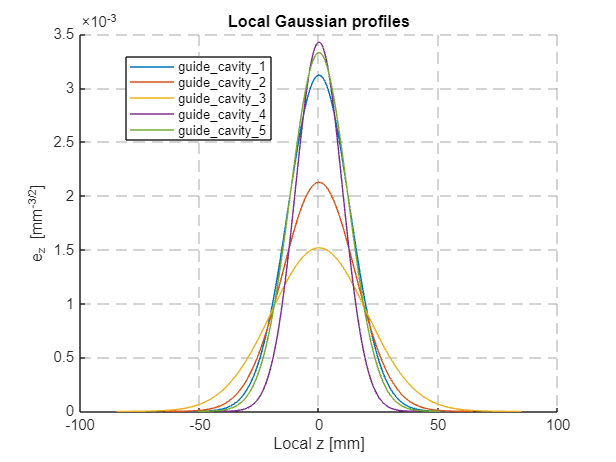


colors = lines(Nc);
style_axes = @(fig) set(findall(fig,'Type','axes'), ...
    'XGrid','on','YGrid','on','GridLineStyle','--', ...
    'GridColor',[0.5 0.5 0.5],'GridAlpha',0.45);

figure('Name','Local Gaussian profiles');
hold on;
for kk=1:Nc
    plot(z_mm(:,kk),e_z(:,kk),'Color',colors(kk,:), ...
        'DisplayName',char(S1(kk)));
end
xlabel('Local z [mm]'); ylabel('e_z [mm^{-3/2}]');
title('Local Gaussian profiles');
legend('Location','best','Interpreter','none');
style_axes(gcf);

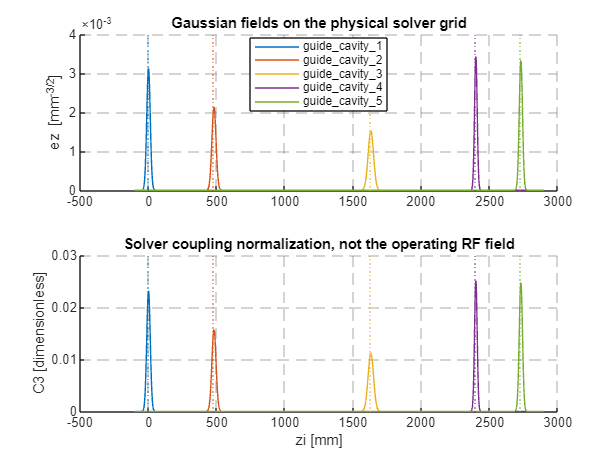


figure('Name','Gaussian fields on the solver grid');
tiledlayout(2,1);
nexttile; hold on;
for kk=1:Nc
    plot(zi,ez(:,kk),'Color',colors(kk,:),'DisplayName',char(S1(kk)));
    xline(zshift(kk),':','Color',colors(kk,:),'HandleVisibility','off');
end
ylabel('ez [mm^{-3/2}]'); title('Gaussian fields on the physical solver grid');
legend('Location','best','Interpreter','none');
nexttile; hold on;
for kk=1:Nc
    plot(zi,C3(:,kk),'Color',colors(kk,:));
    xline(zshift(kk),':','Color',colors(kk,:));
end
xlabel('zi [mm]'); ylabel('C3 [dimensionless]');
title('Solver coupling normalization, not the operating RF field');
style_axes(gcf);

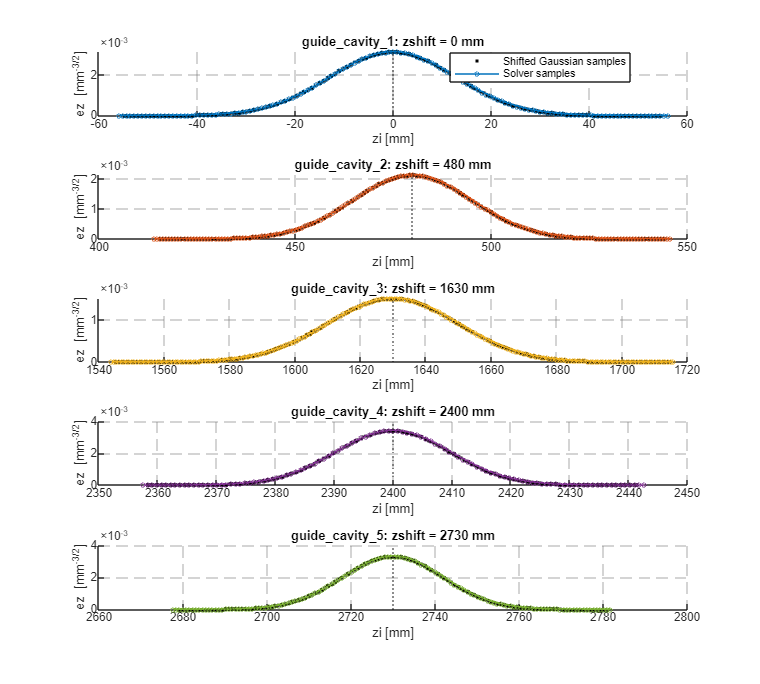


figure('Name','Interpolation cavity by cavity','Position',[100 60 1000 900]);
tiledlayout(Nc,1);
for kk=1:Nc
    nexttile; hold on;
    positions = z_mm(:,kk)+zshift(kk);
    selected = zi >= positions(1)-2*dz & zi <= positions(end)+2*dz;
    plot(positions,e_z(:,kk),'k.','DisplayName','Shifted Gaussian samples');
    plot(zi(selected),ez(selected,kk),'o-','Color',colors(kk,:), ...
        'MarkerSize',3,'DisplayName','Solver samples');
    xline(zshift(kk),':','HandleVisibility','off');
    xlabel('zi [mm]'); ylabel('ez [mm^{-3/2}]');
    title(sprintf('%s: zshift = %g mm',char(S1(kk)),zshift(kk)), 'Interpreter','none');
    if kk==1
        legend('Location','best');
    end
end
style_axes(gcf);

## 7. First numerical checks and normalization integrals

Restore k0 in 1/mm explicitly: all integration coordinates are in mm. This section must not use the Gaussian-generation value of k0 in 1/m. Tolerances here concern the truncated Gaussian/quadrature, not agreement between programming languages.

k0=w0/c/1000; % 1/mm, also safe when this section is run again

assert(all(diff(z_mm)>0,'all'));
assert(all(abs(z_mm+flipud(z_mm)) <= 1e-12,'all'));
assert(all(abs(e_z-flipud(e_z)) <= 1e-15+1e-12*abs(e_z),'all'));
assert(isequal(size(ez),[length(zi),Nc]) && isequal(size(C3),size(ez)));
assert(all(isfinite(ez),'all') && all(isfinite(C3),'all'));
assert(all(vpz == 0,'all') && all(alfaz == 0,'all'));

RtoQ_local=zeros(1,Nc);
M_local=zeros(1,Nc);
RtoQ_grid=zeros(1,Nc);
M_grid=zeros(1,Nc);
for kk=1:Nc
    positions=z_mm(:,kk)+zshift(kk);
    assert(positions(1)-2*dz/10 > zi(1) && positions(end)+2*dz/10 < zi(end));
    outside=zi < positions(1)-2*dz/10 | zi > positions(end)+2*dz/10;
    assert(all(ez(outside,kk)==0));
    expected_C3=ez(:,kk)*eta0*I0/sqrt(k0(kk))/betae/U0/1000;
    assert(all(abs(C3(:,kk)-expected_C3) <= 1e-15+1e-12*abs(expected_C3)), ...
        'C3 normalization is inconsistent. Rerun section 4 with k0 in 1/mm.');

    integral=trapz(z_mm(:,kk),e_z(:,kk));
    transit=trapz(z_mm(:,kk),e_z(:,kk).*exp(-1i*k0(kk)/s*z_mm(:,kk)));
    RtoQ_local(kk)=eta0/k0(kk)*abs(integral)^2;
    M_local(kk)=abs(transit)/abs(integral);
    integral=trapz(zi,ez(:,kk));
    transit=trapz(zi,ez(:,kk).*exp(-1i*k0(kk)/s*(zi-zshift(kk))));
    RtoQ_grid(kk)=eta0/k0(kk)*abs(integral)^2;
    M_grid(kk)=abs(transit)/abs(integral);
end
assert(all(abs(RtoQ_local./RtoQ-1) <= 1e-4));
assert(all(abs(M_local./M-1) <= 1e-4));
assert(all(abs(RtoQ_grid./RtoQ-1) <= 5e-3));
assert(all(abs(M_grid./M-1) <= 5e-3));
disp(table(S1',RtoQ',RtoQ_local',RtoQ_grid',M',M_local',M_grid', ...
    'VariableNames',{'Cavity','RtoQ_input','RtoQ_local','RtoQ_grid','M_input','M_local','M_grid'}));

          Cavity          RtoQ_input    RtoQ_local    RtoQ_grid    M_input    M_local    M_grid 
    __________________    __________    __________    _________    _______    _______    _______

    {'guide_cavity_1'}       182.9        182.89       182.89      0.9225     0.92253     0.9225
    {'guide_cavity_2'}         117        116.99          117       0.893     0.89303      0.893
    {'guide_cavity_3'}      102.06        102.05       102.05      0.8192     0.81924    0.81919
    {'guide_cavity_4'}      123.63        123.63       123.63      0.9518     0.95182     0.9518
    {'guide_cavity_5'}      180.39        180.38       180.38      0.9325     0.93252     0.9325



disp('PASS: MATLAB Gaussian maps, dimensions, padding, C3 and integral checks.');

PASS: MATLAB Gaussian maps, dimensions, padding, C3 and integral checks.


## 8. Export MATLAB results

Overwrites only this test's matlab_results.mat. .mlx and .m run the same calculation. Save -v7 for scipy.io.loadmat.

k0=w0/c/1000; % TEST ONLY: always export the solver wavenumber in 1/mm
save(fullfile(test_directory,'matlab_results.mat'), ...
    'cavityname','z_mm','e_z', ...
    'zi','z','dz','dt','I0','U0','s','betae','k0', ...
    'ez','C3','vpz','alfaz','RtoQ_local','M_local','RtoQ_grid','M_grid','-v7');
fprintf('Saved: %s\n',fullfile(test_directory,'matlab_results.mat'));

Saved: C:\Users\lsito\Desktop\PyKlyC\pyKlyC\test\2.cavity_field_test\matlab_results.mat


disp('Next: run compare_results.ipynb.');

Next: run compare_results.ipynb.
